## Thresholded Subspace Clustering (TSC) Algorithm Demo on Hyperspectral Datasets

###         This Live Script lets you:

- Choose a dataset (Pavia, PaviaUni, Salinas, Indian Pines)

-  Run TSC on the filtered pixels i.e., foreground pixels

- Visualize the resulting cluster map

### Dropdown to select desired dataset

% % Dataset Configuration

this_script_path = matlab.desktop.editor.getActiveFilename;
this_script_folder = fileparts(this_script_path);
proj_root = fileparts(this_script_folder);
addpath(fullfile(proj_root, "TSC_MATLAB"));

clear; clc;

DATASETS = struct( ...
    'Pavia', struct( ...
    'data_file', "Pavia.mat", ...
    'gt_file', "Pavia_gt.mat", ...
    'data_key', "pavia", ...
    'gt_key', "pavia_gt"), ...
    'PaviaUni', struct( ...
    'data_file', "PaviaUni.mat", ...
    'gt_file', "PaviaU_gt.mat", ...
    'data_key', "paviaU", ...
    'gt_key', "paviaU_gt"), ...
    'Salinas', struct( ...
    'data_file', "Salinas_corrected.mat", ...
    'gt_file', "Salinas_gt.mat", ...
    'data_key', "salinas_corrected", ...
    'gt_key', "salinas_gt"), ...
    'Indian_pines', struct( ...
    'data_file', "Indian_pines.mat", ...
    'gt_file', "Indian_pines_gt.mat", ...
    'data_key', "indian_pines", ...
    'gt_key', "indian_pines_gt") ...
);


ds_name = "Pavia";

### Function to run TSC on remote sensing datasets

Running TSC with K=9, max_nz=50, chunk_size=1024, n_init=100, max_iter=100
Building chunked affinity matrix | N=148152, q=50, chunk_size=1024, n_chunks=145
  Processed chunk 1 / 145 (columns 1:1024)
  Processed chunk 2 / 145 (columns 1025:2048)
  Processed chunk 3 / 145 (columns 2049:3072)
  Processed chunk 4 / 145 (columns 3073:4096)
  Processed chunk 5 / 145 (columns 4097:5120)
  Processed chunk 6 / 145 (columns 5121:6144)
  Processed chunk 7 / 145 (columns 6145:7168)
  Processed chunk 8 / 145 (columns 7169:8192)
  Processed chunk 9 / 145 (columns 8193:9216)
  Processed chunk 10 / 145 (columns 9217:10240)
  Processed chunk 11 / 145 (columns 10241:11264)
  Processed chunk 12 / 145 (columns 11265:12288)
  Processed chunk 13 / 145 (columns 12289:13312)
  Processed chunk 14 / 145 (columns 13313:14336)
  Processed chunk 15 / 145 (columns 14337:15360)
  Processed chunk 16 / 145 (columns 15361:16384)
  Processed chunk 17 / 145 (columns 16385:17408)
  Processed chunk 18 / 145 (columns 17409:

Running k-means on embedding of size 148152 x 9 with K=9


Finished TSC with K_used=9


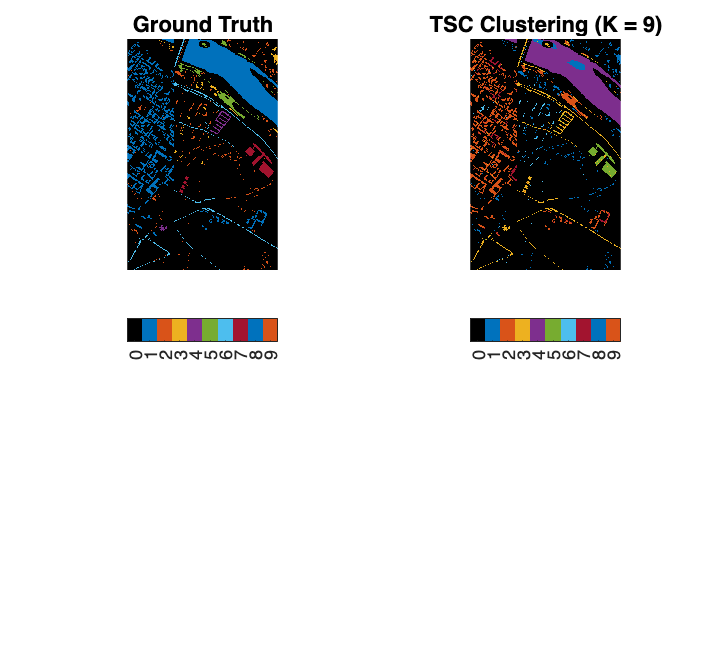

function run_tsc_hsi(ds_name, DATASETS)

    
    cfg = DATASETS.(ds_name);

    % Load Data and Ground Truth

    data_struct = load(fullfile("MAT Files", cfg.data_file));
    gt_struct = load(fullfile("GT Files", cfg.gt_file));

    data_cube = data_struct.(cfg.data_key);
    gt_data = gt_struct.(cfg.gt_key);

    [H, W, B] = size(data_cube);

    % Mask to remove the background pixels

    mask_fg  = gt_data ~= 0;
    mask_vec = mask_fg(:);

    % Determine K from unique non-zero labels

    gt_labels = unique(gt_data);
    gt_labels(gt_labels == 0) = [];
    K = numel(gt_labels);

    % Reshape the data cube to a matrix (D x N)
    % D = Bands; N=pixels
    X_full = reshape(data_cube, [], B);
    X_full = X_full.';
    X = X_full(:, mask_vec);

    % Run TSC on the filtered out pixels
    [~, ~, ~, c, K_used] = tsc(X, K, 'Verbose', true, 'MaxNZ', 50);
    
    % Map cluster labels back to image grid (H x W)
    c_image_vec = zeros(H*W, 1);
    c_image_vec(mask_vec) = c;            % fill only foreground pixels
    c_image = reshape(c_image_vec, H, W);
    
    
    gt_image = gt_data;

    % Visualize clustering result
    figure('Color', 'w', 'Position', [100 100 900 800]);
    
    t = tiledlayout(2,2, ...
        'TileSpacing','compact', ...
        'Padding','compact');
    
    % -------------------------
    % Shared colormap
    % -------------------------
    colors = lines(K);
    cmap = [0 0 0; colors];
    colormap(cmap);
    
    % -------------------------
    % LEFT: Ground Truth
    % -------------------------
    ax1 = nexttile(1);
    imagesc(gt_data);
    axis image off;
    title('Ground Truth', 'FontWeight','bold');
    
    clim([-0.5 K+0.5]);
    
    % -------------------------
    % RIGHT: Clustering
    % -------------------------
    ax2 = nexttile(2);
    imagesc(c_image);
    axis image off;
    title(sprintf('TSC Clustering (K = %d)', K_used), 'FontWeight','bold');
    
    clim([-0.5 K+0.5]);
    
    % -----------
    % Colorbars
    % -----------
    cb1 = colorbar(ax1, 'southoutside');
    cb1.Ticks = 0:K;
    
    cb2 = colorbar(ax2, 'southoutside');
    cb2.Ticks = 0:K;
end

### Run TSC button

run_tsc_hsi(ds_name, DATASETS); 